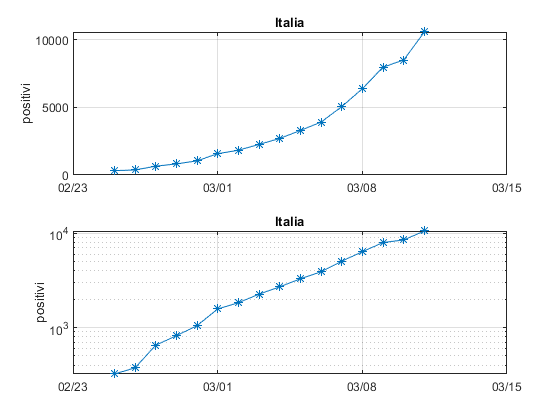


clear all
close all

DatiCorona

t0ITA=datenum(2020,02,24);


titolo='Italia';

posITA=Italia(:,1);
tITA=t0ITA+[1:length(posITA)]';
xITA=tITA-t0ITA;
figura=1;
etichettay='positivi';

plotnatlog(tITA,posITA,figura,etichettay,titolo)


% subplot(2,1,1)
% plot(tITA,posITA,'-o')
% datetick
% grid
% ylabel('positivi')
% title('Italia')
% 
% subplot(2,1,2)
% semilogy(tITA,posITA,'-o')
% datetick
% grid
% ylabel('positivi')
% title('Italia')

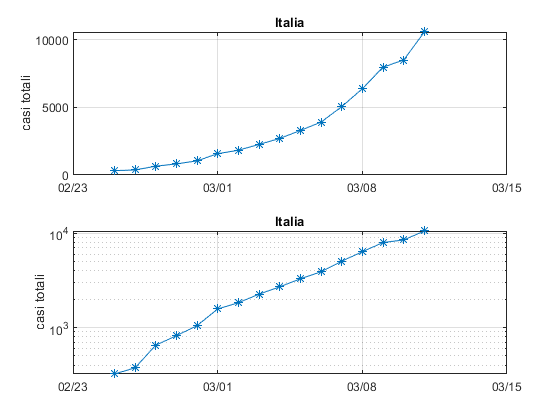

totITA=Italia(:,5);
figura=2;
etichettay='casi totali';

plotnatlog(tITA,posITA,figura,etichettay,titolo)

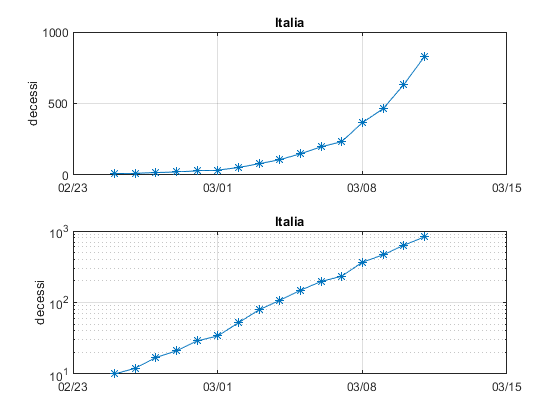

decITA=Italia(:,4);

figura=3;
etichettay='decessi';
titolo='Italia';
plotnatlog(tITA,decITA,figura,etichettay,titolo)

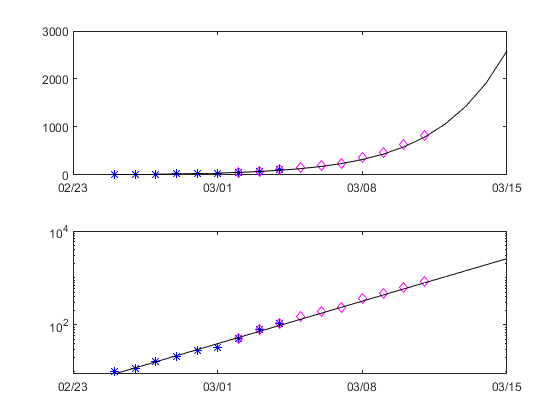

B =     2.2045
    0.2975


BINT =     2.0722    2.3369
    0.2697    0.3253


R =     0.0980
   -0.0172
    0.0336
   -0.0526
   -0.0274
   -0.1659
   -0.0386
    0.0821
    0.0880


RINT =    -0.0646    0.2607
   -0.2233    0.1890
   -0.1820    0.2492
   -0.2712    0.1659
   -0.2527    0.1978
   -0.3177   -0.0140
   -0.2534    0.1763
   -0.1078    0.2720
   -0.0803    0.2562


yhat = 	1.0e+03 *

    0.0091
    0.0122
    0.0164
    0.0221
    0.0298
    0.0401
    0.0540
    0.0728
    0.0980
    0.1319


ttrain=tITA(1:9);
ytrain=decITA(1:9); 
tval=tITA(7:end);
yval=decITA(7:end);
lastday=datenum(2020,03,15);
that=[ttrain(1):lastday]';

figure(100)
yhat = valexp(ttrain,ytrain,tval,yval,that)

X=[ones(size(decITA)) xITA];
[B,BINT,R,RINT] = regress(log(decITA),X)

B =     1.8853
    0.3039


BINT =     1.7994    1.9712
    0.2950    0.3127


R =     0.1134
   -0.0081
    0.0364
   -0.0562
   -0.0373
   -0.1821
   -0.0611
    0.0533
    0.0528
    0.0733


RINT =    -0.0208    0.2476
   -0.1624    0.1462
   -0.1198    0.1925
   -0.2130    0.1006
   -0.1983    0.1237
   -0.3047   -0.0594
   -0.2221    0.1000
   -0.1093    0.2159
   -0.1098    0.2155
   -0.0859    0.2326


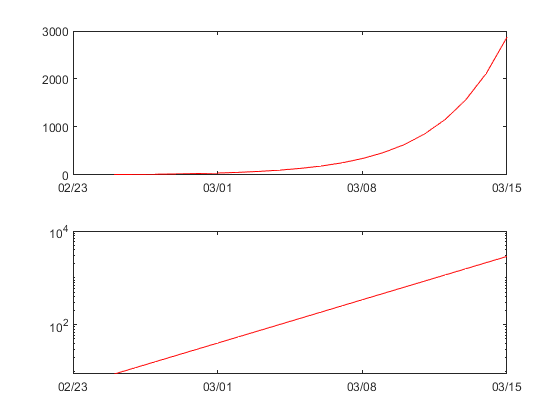



xhat=that-t0ITA;
Xhat=[ones(size(xhat)) xhat];
yhat=Xhat*B;
decITAhat=exp(yhat);

subplot(2,1,1)
plot(that,decITAhat,'-r')
datetick
hold off

subplot(2,1,2)
semilogy(that,decITAhat,'-r')
datetick
hold off

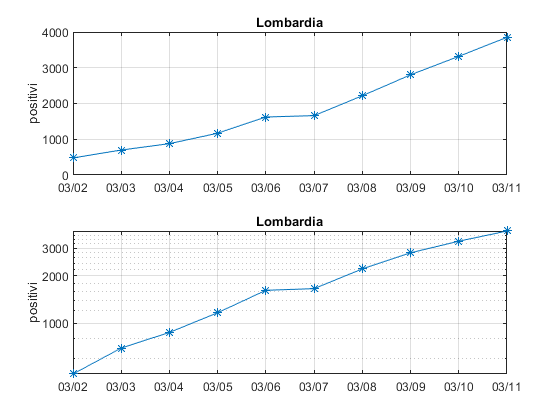

t0=datenum(2020,03,01);

posLOMB=Lomb(:,1);
t=t0+[1:length(posLOMB)]';
titolo='Lombardia';

figura=4;
etichettay='positivi';

plotnatlog(t,posLOMB,figura,etichettay,titolo)

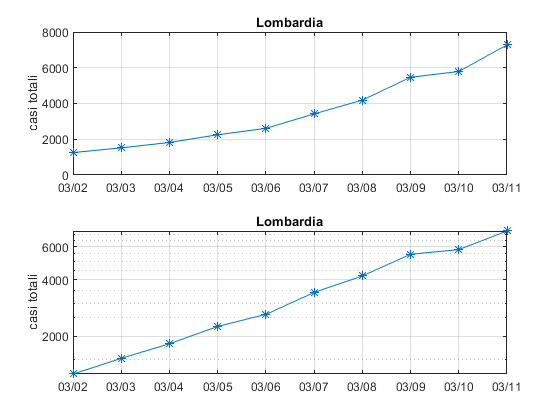

totLOMB=Lomb(:,7);
figura=5;
etichettay='casi totali';

plotnatlog(t,totLOMB,figura,etichettay,titolo)

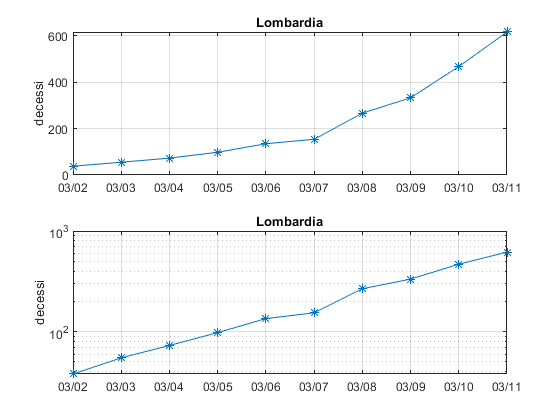

decLOMB=Lomb(:,6);
figura=6;
etichettay='decessi';

plotnatlog(t,decLOMB,figura,etichettay,titolo)

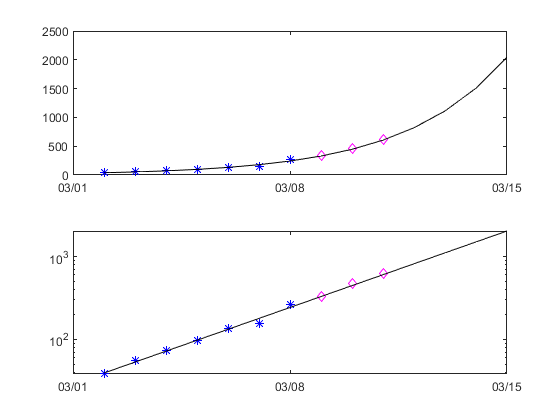

B =     3.6654
    0.3044


BINT =     3.5194    3.8113
    0.2639    0.3449


R =    -0.0278
    0.0376
    0.0163
    0.0064
    0.0223
   -0.1504
    0.0955


RINT =    -0.2132    0.1576
   -0.1748    0.2499
   -0.2171    0.2497
   -0.2329    0.2458
   -0.2101    0.2547
   -0.2154   -0.0854
   -0.0396    0.2307


yhat = 	1.0e+03 *

    0.0391
    0.0530
    0.0718
    0.0974
    0.1320
    0.1790
    0.2427
    0.3290
    0.4461
    0.6048


ttrain=t(1:7);
ytrain=decLOMB(1:7); 
tval=t(8:end);
yval=decLOMB(8:end);
lastday=datenum(2020,03,15);
that=[ttrain(1):lastday]';

figure(200)
yhat = valexp(ttrain,ytrain,tval,yval,that)